clear;
close all;

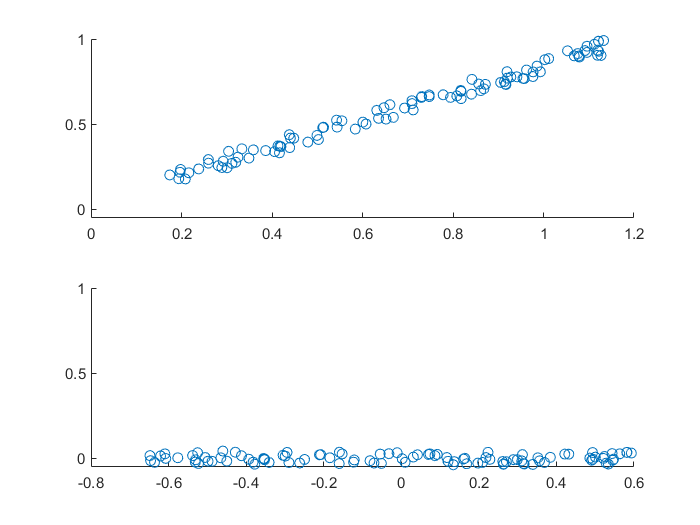

% Pount cloud creation
x = rand(1,100) + rand(); % 100 punts aleatoris amb offset aleatori
y = rand().*x + rand(1,100)/10; % pendent de valor aleatori i offset aleatori
ax(1) = subplot(2,1,1);
scatter(x,y);

% Cloud point centering
xp = x - mean(x);
yp = y - mean(y);

% Covariance and eigenvalues
C = cov(xp, yp);
[evectors, evalues] = eig(C);

% Determine which dimension has the major variance
[val, ind] = max(diag(evalues));

% Extract the angle of the 'major axis'
theta = -pi/2 - atan2(evectors(1,ind), evectors(2,ind));

% Create clockwise rotation matrix
R = [cos(theta) sin(theta); -sin(theta) cos(theta)];

% Rotate the points
rp = R * [xp;yp];

ax(2) = subplot(2,1,2);
scatter(rp(1,:),rp(2,:));
linkaxes(ax,'y');